%load the Wine Dataset already extracted from http://www.models.life.ku.dk/Wine_GCMS_FTIR
load('Wine_v7.mat')
%plot the Infrared Spectra
plot(axis_spectra_wavenumber,IR_spectra)
Label_Wine_samples = categorical(strtok(Label_Wine_samples,'-')); % this removes unnecesary information and leaves the country name intact
IRData = table(cellstr(Label_Wine_samples),IR_spectra)

IRData = 44×2 table
    Var1       IR_spectra  
    _____    ______________

    'ARG'    [1x842 double]
    'ARG'    [1x842 double]
    'ARG'    [1x842 double]
    'ARG'    [1x842 double]
    'ARG'    [1x842 double]
    'ARG'    [1x842 double]
    'AUS'    [1x842 double]
    'AUS'    [1x842 double]
    'AUS'    [1x842 double]
    'AUS'    [1x842 double]
    'AUS'    [1x842 double]
    'AUS'    [1x842 double]
    'AUS'    [1x842 double]
    'AUS'    [1x842 double]
    'AUS'    [1x842 double]
    'AUS'    [1x842 double]


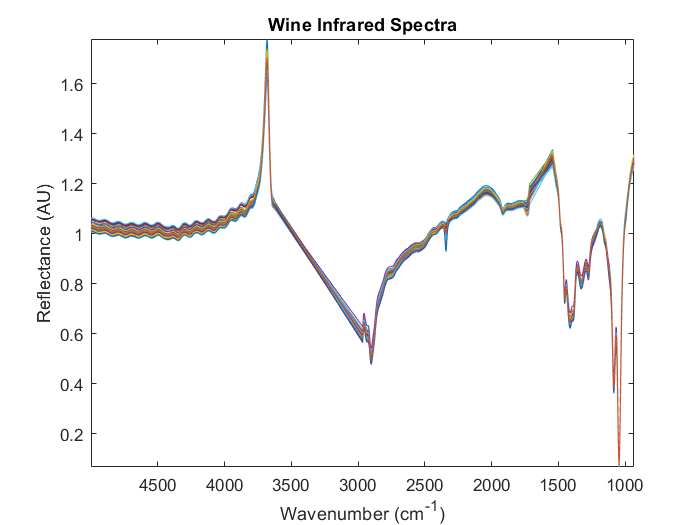


%Infrared wavenumber data is presented from higher wavenumber to lower wavenumber
set(gca,'Xdir','reverse')
%set the axis wavenumbers to fit the data
axis tight
%label the axes
xlabel('Wavenumber (cm^-^1)')
ylabel('Reflectance (AU)')
title('Wine Infrared Spectra')
legend(cellstr(Label_Wine_samples))
legend off

%Plot the GC data
[m n] =size(Elution_profiles)

m =     44


n =         2700


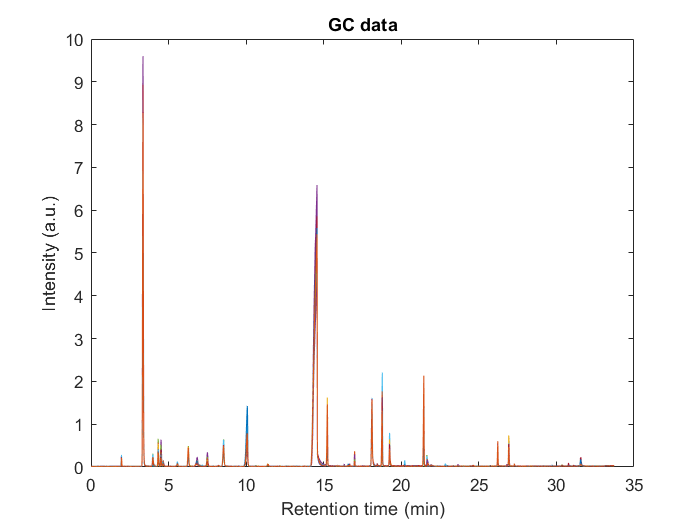

Data= zeros(size(Elution_profiles));
plot(cell2mat(Label_Elution_time),Elution_profiles);
xlabel('Retention time (min)')
ylabel('Intensity (a.u.)')
legend(cellstr(Label_Wine_samples))
title('GC data')
legend off

GCData = table(cellstr(Label_Wine_samples),Elution_profiles)

GCData = 44×2 table
    Var1     Elution_profiles
    _____    ________________

    'ARG'    [1x2700 double] 
    'ARG'    [1x2700 double] 
    'ARG'    [1x2700 double] 
    'ARG'    [1x2700 double] 
    'ARG'    [1x2700 double] 
    'ARG'    [1x2700 double] 
    'AUS'    [1x2700 double] 
    'AUS'    [1x2700 double] 
    'AUS'    [1x2700 double] 
    'AUS'    [1x2700 double] 
    'AUS'    [1x2700 double] 
    'AUS'    [1x2700 double] 
    'AUS'    [1x2700 double] 
    'AUS'    [1x2700 double] 
    'AUS'    [1x2700 double] 
    'AUS'    [1x2700 double] 



%Plot the MS data
[m n] =size(Mass_profiles)

m =     44


n =    200


Data= zeros(size(Elution_profiles));
plot(cell2mat(Label_Mass_channels),Mass_profiles)
xlabel('m/z')
ylabel('Abundance (a.u.)')
title('MS Data')
legend(cellstr(Label_Wine_samples))
legend off
MSData = table(Class,Mass_profiles)

MSData = 44×2 table
    Class    Mass_profiles 
    _____    ______________

      1      [1x200 double]
      1      [1x200 double]
      1      [1x200 double]
      1      [1x200 double]
      1      [1x200 double]
      1      [1x200 double]
      2      [1x200 double]
      2      [1x200 double]
      2      [1x200 double]
      2      [1x200 double]
      2      [1x200 double]
      2      [1x200 double]
      2      [1x200 double]
      2      [1x200 double]
      2      [1x200 double]
      2      [1x200 double]


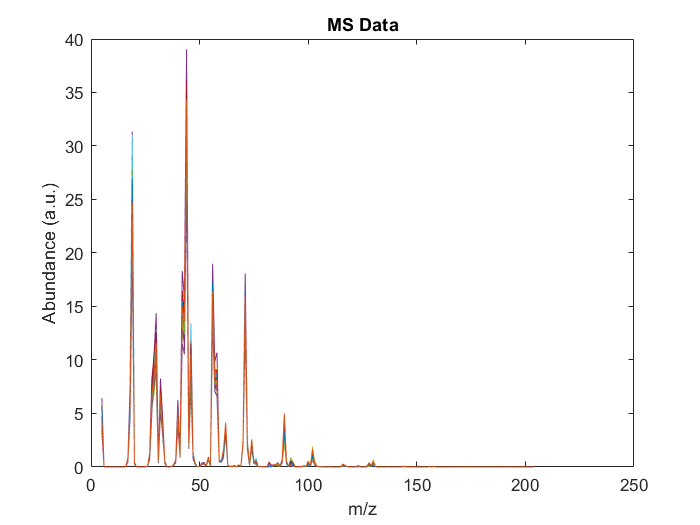




hold off %when finished loading the spectra